Consider a disc of radius $\alpha \;$ tolling down a ramp whose height at position $x$ is $f\left(x\right)$. Say that the center of the ball, which is also the center of mass is at position $\left(x\left(t\right),y\left(t\right)\right)$ and that the disc contacts the ramp at position $\left(\textrm{cpx}\left(t\right),\textrm{cpy}\left(t\right)\right)$ .

clear all
syms x(t) y(t) theta1(t) theta2(t) cpx(t) cpy(t) f(z) F1(t) F2(t) s 
%Set paramters. 
m=1; alpha=0.25; g=9.81;

%Make a ramp.  Make it not *too* steep, though, because we have trouble if it gets too steep.  Somthing like this.  
f(z)=10/(z+1)*sin(z);
%f(z) = z^2;

%The tangnential direction to the wire is
T=[1;diff(f)]/sqrt(1+diff(f)^2)

$$T(z) = \begin{array}{l} \left(\begin{array}{c} \frac{1}{\sigma_{1}}\\ \frac{\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\sigma_{2}}^{2}+1}\\ \sigma_{2}=\frac{10\,\cos\left(z\right)}{z+1}-\frac{10\,\sin\left(z\right)}{{\left(z+1\right)}^{2}} \end{array}$$


%The normal direction to the wire is
N=[-diff(f);1]/sqrt(1+diff(f)^2)

$$N(z) = \begin{array}{l} \left(\begin{array}{c} -\frac{\sigma_{2}}{\sigma_{1}}\\ \frac{1}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\sigma_{2}}^{2}+1}\\ \sigma_{2}=\frac{10\,\cos\left(z\right)}{z+1}-\frac{10\,\sin\left(z\right)}{{\left(z+1\right)}^{2}} \end{array}$$


%MOI of disc about COM. 
IG=1/2*m*alpha^2;

%Position of COM.
rG=[x(t);y(t)];

%Contact point
cp=[cpx(t);cpy(t)];

%Contact forces. 
F=F1(t)*T(cpx(t))+F2(t)*N(cpx(t));

%COLM
eq1=m*diff(rG,2)==F-m*[0;g]

$$eq1 = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F_{1}\left(t\right)}{\sigma_{1}}-\frac{F_{2}\left(t\right)\,\sigma_{2}}{\sigma_{1}}\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{F_{2}\left(t\right)}{\sigma_{1}}+\frac{F_{1}\left(t\right)\,\sigma_{2}}{\sigma_{1}}-\frac{981}{100} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\sigma_{2}}^{2}+1}\\ \sigma_{2}=\frac{10\,\cos\left(\mathrm{cpx}\left(t\right)\right)}{\mathrm{cpx}\left(t\right)+1}-\frac{10\,\sin\left(\mathrm{cpx}\left(t\right)\right)}{{\left(\mathrm{cpx}\left(t\right)+1\right)}^{2}} \end{array}$$

%COAM --- use theta1+theta2 in place of theta. 
MFG=cross([cp-rG;0],[F;0]);
eq2=IG*diff(theta1+theta2,2)==MFG(3)

$$eq2(t) = \begin{array}{l} \frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)}{32}+\frac{\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{32}=\left(\frac{F_{2}\left(t\right)}{\sigma_{1}}+\frac{F_{1}\left(t\right)\,\sigma_{2}}{\sigma_{1}}\right)\,\left(\mathrm{cpx}\left(t\right)-x\left(t\right)\right)-\left(\frac{F_{1}\left(t\right)}{\sigma_{1}}-\frac{F_{2}\left(t\right)\,\sigma_{2}}{\sigma_{1}}\right)\,\left(\mathrm{cpy}\left(t\right)-y\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\sigma_{2}}^{2}+1}\\ \sigma_{2}=\frac{10\,\cos\left(\mathrm{cpx}\left(t\right)\right)}{\mathrm{cpx}\left(t\right)+1}-\frac{10\,\sin\left(\mathrm{cpx}\left(t\right)\right)}{{\left(\mathrm{cpx}\left(t\right)+1\right)}^{2}} \end{array}$$

Ok, for the constraints.  Certainly the center of the ball must be $\alpha \;$ from the contact point.  I think it is true that in order for the ball to be nice an tangent to the curve, the center of the ball must be $\alpha \;$ units from the contact point in the orthogonal from the ramp direction.  So like this: 



%rG must be alpha from cp in the normal direction from (cpx,xpy).
eq4=rG==[cpx;cpy]+alpha*N(cpx)

$$eq4(t) = \begin{array}{l} \left(\begin{array}{c} x\left(t\right)=\mathrm{cpx}\left(t\right)-\frac{\sigma_{2}}{\sigma_{1}}\\ y\left(t\right)=\mathrm{cpy}\left(t\right)+\frac{1}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,\sqrt{{\sigma_{2}}^{2}+1}\\ \sigma_{2}=\frac{10\,\cos\left(\mathrm{cpx}\left(t\right)\right)}{\mathrm{cpx}\left(t\right)+1}-\frac{10\,\sin\left(\mathrm{cpx}\left(t\right)\right)}{{\left(\mathrm{cpx}\left(t\right)+1\right)}^{2}} \end{array}$$

%cp must be on the wire. 
eq5=cpy==f(cpx)

$$eq5(t) = \mathrm{cpy}\left(t\right)=\frac{10\,\sin\left(\mathrm{cpx}\left(t\right)\right)}{\mathrm{cpx}\left(t\right)+1}$$

%Function to evaluate f'(x). 
df=diff(f);

%Function to evaluate theta1 at point x. 
calcTheta1=@(z) atan(df(z));

%Require that diff(theta1(cpx(t)))==diff(atan(-f'(cpx(t)))
eq6=diff(theta1)==diff(calcTheta1(cpx(t)))

$$eq6(t) = \begin{array}{l} \frac{\partial }{\partial t}\theta_{1}\left(t\right)=-\frac{\frac{20\,\cos\left(\mathrm{cpx}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{cpx}\left(t\right)}{\sigma_{1}}+\frac{10\,\sin\left(\mathrm{cpx}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{cpx}\left(t\right)}{\mathrm{cpx}\left(t\right)+1}-\frac{20\,\sin\left(\mathrm{cpx}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{cpx}\left(t\right)}{{\left(\mathrm{cpx}\left(t\right)+1\right)}^{3}}}{{\left(\frac{10\,\cos\left(\mathrm{cpx}\left(t\right)\right)}{\mathrm{cpx}\left(t\right)+1}-\frac{10\,\sin\left(\mathrm{cpx}\left(t\right)\right)}{\sigma_{1}}\right)}^{2}+1}\\ \mathrm{where}\\ \sigma_{1}={\left(\mathrm{cpx}\left(t\right)+1\right)}^{2} \end{array}$$

%Roll without slip. 
eq7=alpha*diff(theta2)==-sqrt(1+df(cpx(t))^2)*diff(cpx)

$$eq7(t) = \frac{\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{4}=-\sqrt{{\left(\frac{10\,\cos\left(\mathrm{cpx}\left(t\right)\right)}{\mathrm{cpx}\left(t\right)+1}-\frac{10\,\sin\left(\mathrm{cpx}\left(t\right)\right)}{{\left(\mathrm{cpx}\left(t\right)+1\right)}^{2}}\right)}^{2}+1}\,\frac{\partial }{\partial t}\mathrm{cpx}\left(t\right)$$



%Equations of motion
DEs=[eq1;eq2];

%The position constraints are 4 and 5. 
positionConstraint=[eq4;eq5];

%The velocity constraints are 6 and 7
velocityConstraint=[eq6;eq7];


%Solve! Start in a feasible configuration though, by which I mean theta1
%should be correct for the initial contact point.  Though, I don't think it
%matters. Theta2(0) really doesn't matter, all it is doing is defining
%where the "reference" point, O in the figure, is on the figure.  By
%setting it equal to 0 you are setting it to be the point antipodal to cp(0) at time 0.  
cpx0=1;

soln=mechanicsAsDAE(DEs,positionConstraint,velocityConstraint,[0,2],[theta1==calcTheta1(cpx0), cpx==cpx0, theta2==0, diff(theta2)==-5]);

The unknown functions (just the base functions, not derivatives) are: F1(t),F2(t),cpx(t),cpy(t),theta1(t),theta2(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
F1: 1.677929 F1t:0.000000
F2: 0.066310 F2t:0.000000
cpx: 1.000000 cpxt:1.072890
cpy: 4.207355 cpyt:0.641410
theta1: 0.538825 theta1t:-3.798009
theta2: 0.000000 theta2t:-5.000000
x: 0.871718 xt:1.887859
y: 4.421933 yt:1.128627
Dcpxt: 1.072890 Dcpxtt:-1.889755
Dcpyt: 0.641410 Dcpytt:-6.660979
Dtheta1t: -3.798009 Dtheta1tt:-6.736308
Dtheta2t: -5.000000 Dtheta2tt:20.159740
Dxt: 1.887859 Dxtt:1.406161
Dyt: 1.128627 Dytt:-8.892093


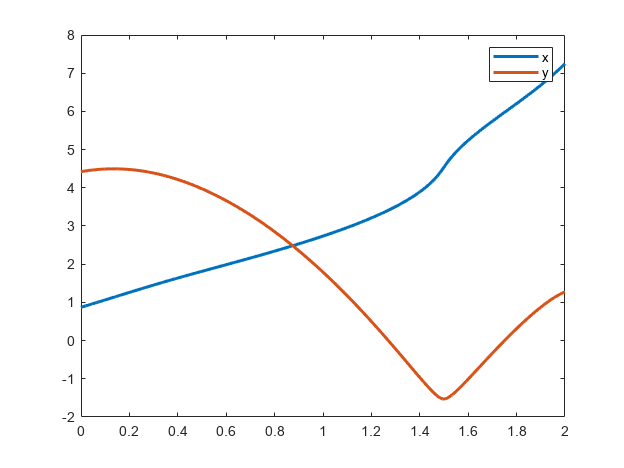

KLE=1/2*m*(soln.Dxt.^2+soln.Dyt.^2);
KRE=1/2*IG*(soln.Dtheta1t+soln.Dtheta2t).^2;
PE=m*soln.y*g;
plot(soln.t,soln.x,soln.t,soln.y,'LineWidth',2); legend({"x","y"});

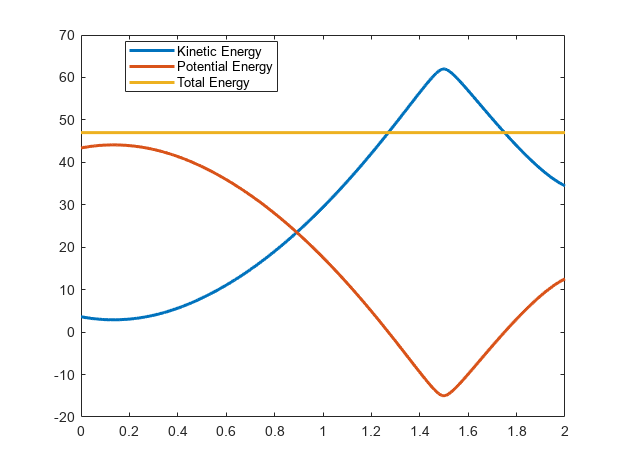

plot(soln.t,KLE+KRE,soln.t,PE,soln.t,KLE+KRE+PE,'LineWidth',2); legend({'Kinetic Energy', 'Potential Energy', 'Total Energy'},'Location','Best'); 

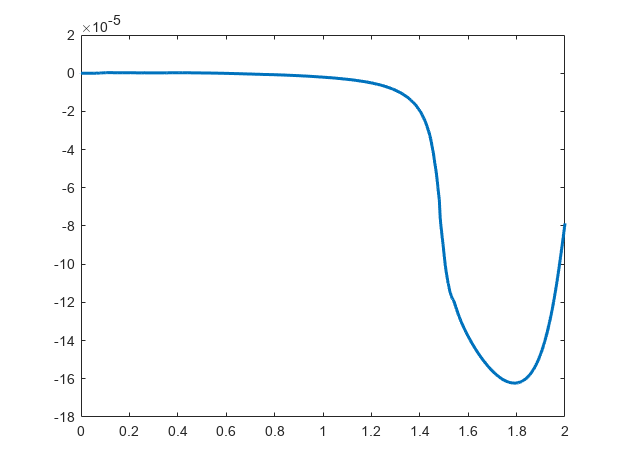

plot(soln.t,KLE+KRE+PE - KLE(1)-KRE(1)-PE(1),'LineWidth',2)

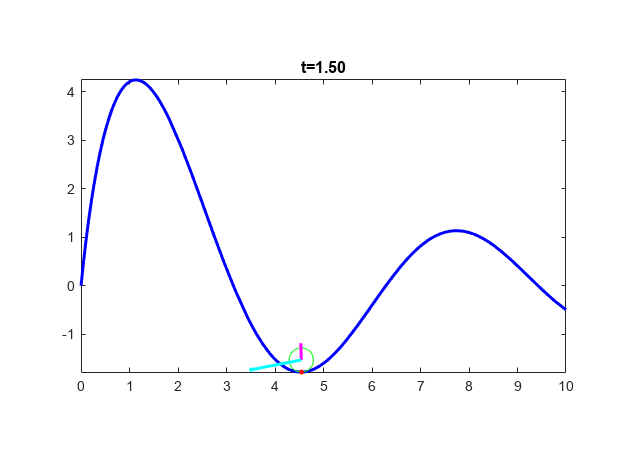

xinterp=makeSplineFun(soln.t,soln.x);
yinterp=makeSplineFun(soln.t,soln.y);

cpxinterp=makeSplineFun(soln.t,soln.cpx);
cpyinterp=makeSplineFun(soln.t,soln.cpy);

theta1interp=makeSplineFun(soln.t,soln.theta1);
theta2interp=makeSplineFun(soln.t,soln.theta2);

for tt=linspace(0,2,101)
    drawframe([0,10],f,alpha,[xinterp(tt);yinterp(tt)],[cpxinterp(tt),cpyinterp(tt)],theta1interp(tt),theta2interp(tt),tt);
    drawnow;
end


%[govDEs,PPs]=analyzeSystem(DEs,positionConstraint,velocityConstraint,[theta1,diff(theta2),x,diff(x)]);
%soln=timeStepODESystem(govDEs,[0,10],[theta==0,diff(theta)==1,x==0],PPs,0);
%plot(soln.t,soln.x,soln.t,soln.y,soln.t,soln.theta,'LineWidth',2); legend({"x","y","theta"}); grid on;


function drawframe(lims,f,r,rG,cp,theta1,theta2,t)
    fplot(f,lims,'LineWidth',2,'Color','blue');
    gammas=linspace(0,2*pi,100);
    hold on;
    plot(rG(1)+r*cos(gammas),rG(2)+r*sin(gammas),'Color','green');

    quiver(rG(1),rG(2),-1.5*r*sin(theta1),1.5*r*cos(theta1),'LineWidth',2,"Color",'magenta');

    quiver(rG(1),rG(2),-1.5*sin(theta1+theta2),1.5*r*cos(theta1+theta2),'LineWidth',2,"color","cyan");
    plot(cp(1),cp(2),'.','MarkerSize',10,"Color","red")
    if exist('t','var')
        title(sprintf("t=%.2f",t));
    end
    axis equal
    hold off
end

function f=makeSplineFun(x,y)
    pp=spline(x,y);
    f=@(x) ppval(pp,x);
end
